P =     1.0095    0.0095         0         0         0         0
    0.9634    1.9649    0.0015         0         0         0
         0    0.0001    1.0006    0.0005         0         0
         0         0    0.0002    1.8680    0.8678         0
         0         0         0    0.0362    1.1570    0.1207


beta = 0.5000

Matrix dimensions must agree.

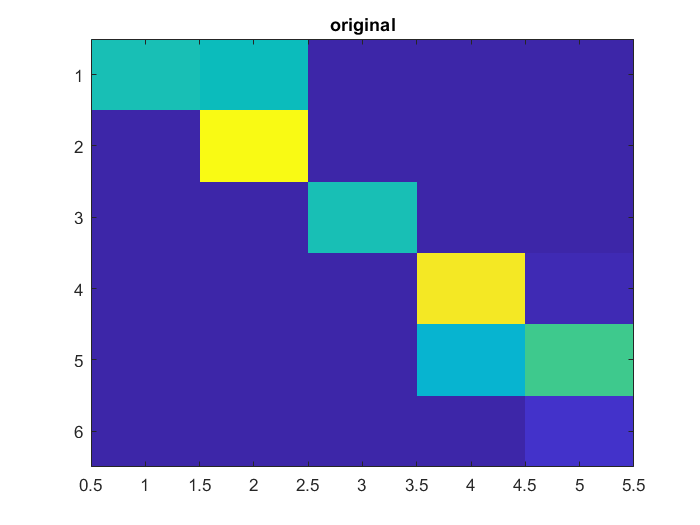



t = 0:5;
s = t;
% by cols: locations, by rows: time
P = [1.0095,0.0095,0,0,0,0;0.9634,1.9649,0.0015,0,0,0;0,0.0001,1.0006,0.0005,0,0;0,0,0.0002,1.8680,0.8678,0;0,0,0,0.0362,1.1570,0.1207;]
X = P';
V= X(1:5,:);
b = V;
dX = V;

w0 = P(1,:);
O = X(1:5,:);
D = X(2:6,:);
M = 6;
const = 0.57721;
%fix beta and change alpha, c = mu - beta*log(-log(p))+const
betah = 0.1:0.8; %high-noise
betal = 1:30; %low-noise
beta = 0.5 %simulation
% determine k and eps with deterministic model 
W = exp(-X(1,:).^2/2)/sqrt(2*pi*1);
mu = mean(X(1,:));
sigma = var(X(1,:));
B = exp(mu-sigma^2*t/2+sigma*W);
W1 = exp(-X(2,:).^2/2)/sqrt(2*pi*1);
mu1 = mean(X(2,:));
sigma1 = var(X(2,:));
B1 = exp(mu1-sigma1^2*t/2+sigma1*W1);
k = sigma*B/W-1;
% W1 -W = eps1*W1*(D(1,:)-k*W(1,:))+sigma1*W1*(B1-B)
eps1 = (W1-W-sigma1*W1.*(B1-B))/W1./(D(1,:)-k*W(1,:));
eps = mean(eps1);
for alpha = [0.5,1,1.5,2]
    for i = 1:M-1
        if i ==1
            for j = 2:M
                for t = 1:5
                    if t == 1
                        mui = X(j,1);
                        vari = X(j,1);
                        c = mui - beta*log(-log(normpdf(mui)))+const
                        W = exp(-X(i,:).^2/2)/sqrt(2*pi*1);
                        V(i,t) = -eps*(1/alpha*(O(i,1).*log(exp(alpha*X(j,1)-beta*c))))+k*exp(X(j,1)); 
                        b(i,t) = exp(mui-vari*t/2+std(X(j,1:t))*W(t));
                    else
                        mui = mean(X(j,1:t));
                        vari = var(X(j,1:t));
                        c = mui - beta*log(-log(normpdf(mui)))+const
                        W = exp(-X(j,:).^2/2)/sqrt(2*pi*1);
                        V(i,t) = -eps*(1/alpha*sum(O(i,1:t).*log(sum(exp(alpha*X(j,1:t)-beta*c))))+k*sum(exp(X(j,1:t))));
                        b(i,t) = exp(mui-vari*t/2+std(X(j,1:t))*W(t));
                    end       
                end
            end
            dX(i,:)=(-V(i,:)+sqrt(vari)*b(i,:));
        else
            for j  = [1:i-1,i+1:M]
                for t = 1:5
                    if t == 1
                        mui = X(j,1);
                        vari = X(j,1:t);
                        c = mui - beta*log(-log(normpdf(mui)))+const
                        W = exp(-X(j,:).^2/2)/sqrt(2*pi*1);
                        V(i,t) = -eps*(1/alpha*(O(i,t).*log(exp(alpha*X(j,t)-beta*c))))+k*exp(X(j,t)); 
                        b(i,t) = exp(mui-vari*t/2+std(X(j,1:t))*W(t));
                    else
                        mui = mean(X(j,1:t));
                        vari = var(X(j,1:t));
                        c = mui - beta*log(-log(normpdf(mui)))+const
                        W = exp(-X(j,:).^2/2)/sqrt(2*pi*1);
                        V(i,t) = -eps*(1/alpha*(O(i,t).*log(exp(alpha*X(j,t)-beta*c))))+k*exp(X(j,t)); 
                        b(i,t) = exp(mui-vari*t/2+std(X(j,1:t))*W(t));
                    end       
                end            
            end
            dX(i,:)=(-V(i,:)+sqrt(vari)*b(i,:));
        end
    end
end

Xhat = X;
for dt = 1:5
    Xhat(1+dt,:) = X(dt,:) + dX(dt,:)/sum(dX(dt,:));
end
Xhat(Xhat<0) = 0;

figure,
imagesc(X);
title('original')

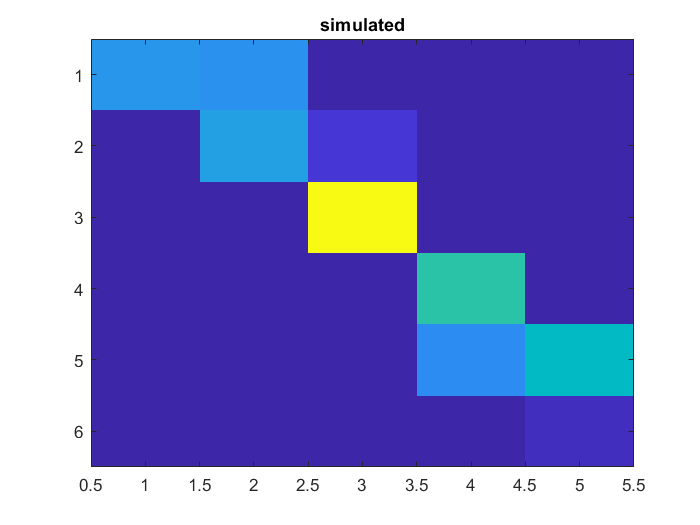

figure,
imagesc(Xhat);
title('simulated')

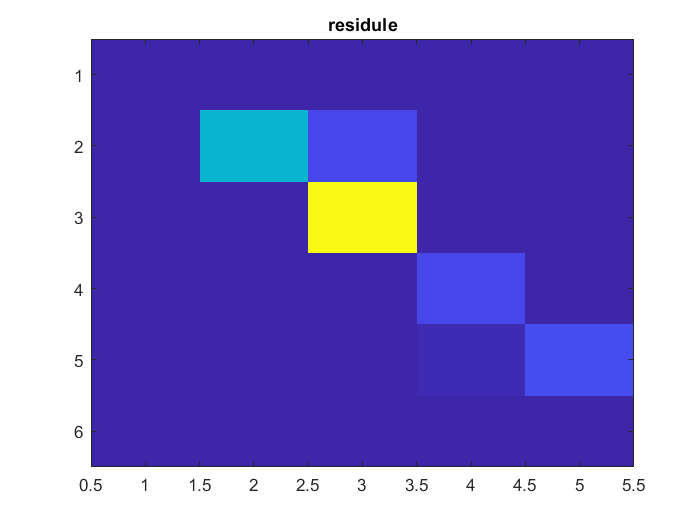

figure,
imagesc(abs(Xhat-X));
title('residule')